% Images Datapath – Please modify your path accordingly
datapath='Cov3';

% Image Datastore
imds=imageDatastore(datapath, ...
'IncludeSubfolders',true, ...
'LabelSource','foldernames');

% Determine the split up
total_split=countEachLabel(imds)

total_split = 2×2 table
     Label      Count
    ________    _____

    COVID-19    1281 
    Normal      3270 


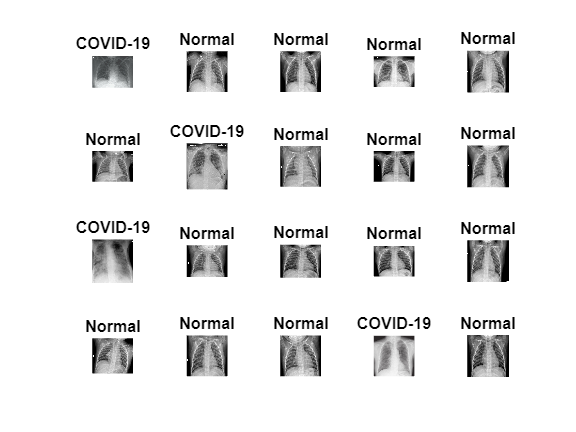


% Number of Images
num_images=length(imds.Labels);

% Visualize random 20 images
perm=randperm(num_images,20);
figure;
for idx=1:20

 subplot(4,5,idx);
 imshow(imread(imds.Files{perm(idx)}));
 title(sprintf('%s',imds.Labels(perm(idx))))

end

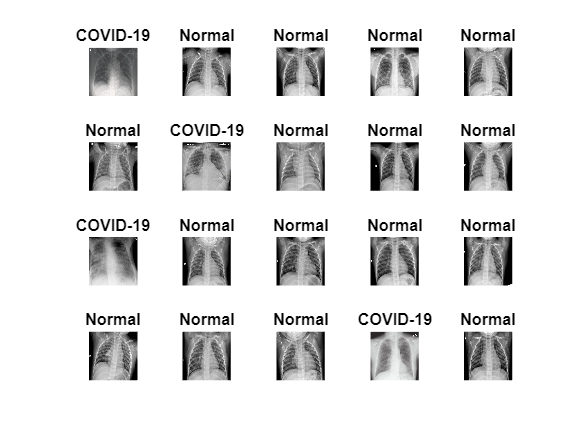


figure;

for idx=1:20
 subplot(4,5,idx);
 imshow(preprocess_images(imds.Files{perm(idx)},[250 250]))
 title(sprintf('%s',imds.Labels(perm(idx))))
end



% Split the Training and Testing Dataset
train_percent=0.80;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');
% Split the Training and Validation
valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain);


% Load AlexNet
net=alexnet;
 
% Transfer the layers except the last 3 layers
layersTransfer=net.Layers(1:end-3);
 
% Clear the existing alexnet architecture
clear net;
 
% Define the new layers 
numClasses=numel(categories(imdsTrain.Labels));

    cllayer0 = convolution2dLayer(3,16,'Padding','same','Name','conv_0')

cllayer0 =   Convolution2DLayer with properties:

              Name: 'conv_0'

   Hyperparameters
        FilterSize: [3 3]
       NumChannels: 'auto'
        NumFilters: 16
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'same'
       PaddingSize: []
      PaddingValue: 0

   Learnable Parameters
           Weights: []
              Bias: []

  Show all properties


    bnlayer0 = batchNormalizationLayer('Name','BN_0')

bnlayer0 =   BatchNormalizationLayer with properties:

               Name: 'BN_0'
        NumChannels: 'auto'

   Hyperparameters
          MeanDecay: 0.1000
      VarianceDecay: 0.1000
            Epsilon: 1.0000e-05

   Learnable Parameters
             Offset: []
              Scale: []

   State Parameters
        TrainedMean: []
    TrainedVariance: []

  Show all properties



    cllayer1 = convolution2dLayer(3,16,'Padding','same','Name','conv_1')

cllayer1 =   Convolution2DLayer with properties:

              Name: 'conv_1'

   Hyperparameters
        FilterSize: [3 3]
       NumChannels: 'auto'
        NumFilters: 16
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'same'
       PaddingSize: []
      PaddingValue: 0

   Learnable Parameters
           Weights: []
              Bias: []

  Show all properties


    bnlayer1 = batchNormalizationLayer('Name','BN_1')

bnlayer1 =   BatchNormalizationLayer with properties:

               Name: 'BN_1'
        NumChannels: 'auto'

   Hyperparameters
          MeanDecay: 0.1000
      VarianceDecay: 0.1000
            Epsilon: 1.0000e-05

   Learnable Parameters
             Offset: []
              Scale: []

   State Parameters
        TrainedMean: []
    TrainedVariance: []

  Show all properties



    cllayer2 = convolution2dLayer(3,16,'Padding','same','Name','conv_2')

cllayer2 =   Convolution2DLayer with properties:

              Name: 'conv_2'

   Hyperparameters
        FilterSize: [3 3]
       NumChannels: 'auto'
        NumFilters: 16
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'same'
       PaddingSize: []
      PaddingValue: 0

   Learnable Parameters
           Weights: []
              Bias: []

  Show all properties


    bnlayer2 = batchNormalizationLayer('Name','BN_2')

bnlayer2 =   BatchNormalizationLayer with properties:

               Name: 'BN_2'
        NumChannels: 'auto'

   Hyperparameters
          MeanDecay: 0.1000
      VarianceDecay: 0.1000
            Epsilon: 1.0000e-05

   Learnable Parameters
             Offset: []
              Scale: []

   State Parameters
        TrainedMean: []
    TrainedVariance: []

  Show all properties



    relulayer = reluLayer('Name','relu_1')

relulayer =   ReLULayer with properties:

    Name: 'relu_1'


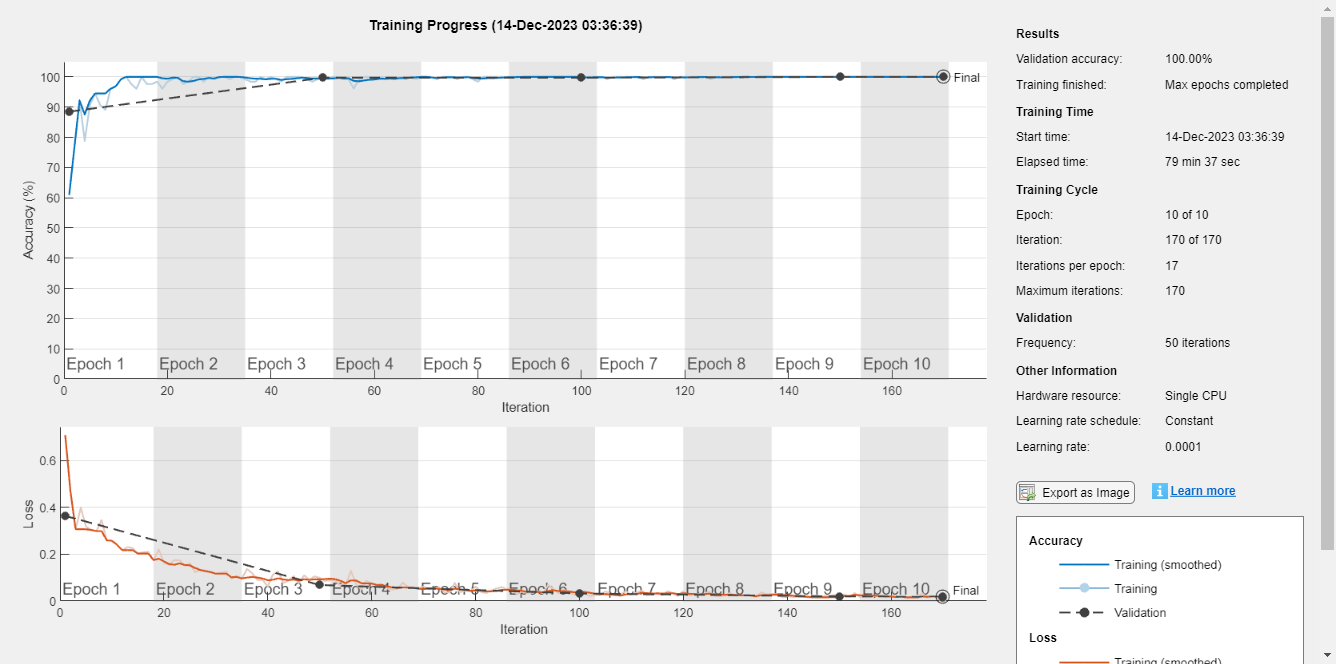

 
% New layers 
layers=[
    layersTransfer
    cllayer0
    bnlayer0
    cllayer1
    bnlayer1
    cllayer2
    bnlayer2
    relulayer
    fullyConnectedLayer(numClasses,'WeightLearnRateFactor',20,'BiasLearnRateFactor',20)
    softmaxLayer
    classificationLayer];

analyzeNetwork(layers)


options=trainingOptions('adam', ...
    'MiniBatchSize',128, ...
    'MaxEpochs',10, ...
    'Shuffle','every-epoch', ...
    'InitialLearnRate',1e-4, ...
    'ValidationData',imdsValid, ...
    'ValidationFrequency',50,'ValidationPatience',4, ...
    'Verbose',false, ...
    'Plots','training-progress');

numTrainingFiles = 0.7;
[imdsTrain,imdsValidation] = splitEachLabel(imdsTrain,numTrainingFiles);

rng(42);
 
    imdsTrain.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsTest.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsValidation.ReadFcn = @(filename)preprocess_Xray(filename);
    
 
    
    % Data Augumentation
    augmenter = imageDataAugmenter( ...
        'RandRotation',[-5 5],'RandXReflection',1,...
        'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);
    
    % Resizing all training images to [224 224] for ResNet architecture
    auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
    imdsValidationAug = augmentedImageDatastore([224 224],imdsValidation,'DataAugmentation',augmenter);
   

   
imdsTrain.ReadFcn=@(filename)preprocess_images(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);
imdsValid.ReadFcn=@(filename)preprocess_images(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);



% Train the network
netTransfer=trainNetwork(imdsTrain,layers,options);

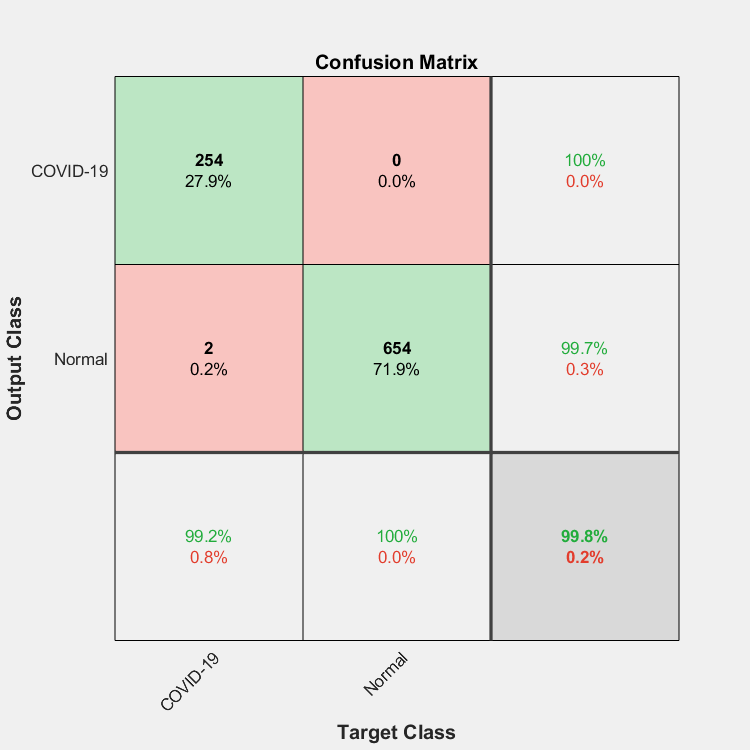


% Preprocess the test cases similar to the training
imdsTest.ReadFcn=@(filename)preprocess_images(filename,[layers(1).InputSize(1), layers(1).InputSize(2)]);

% Predict Test Labels using Classify command
[predicted_labels,posterior]=classify(netTransfer,imdsTest);


% Actual Labels
actual_labels=imdsTest.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels)
title('Confusion Matrix');

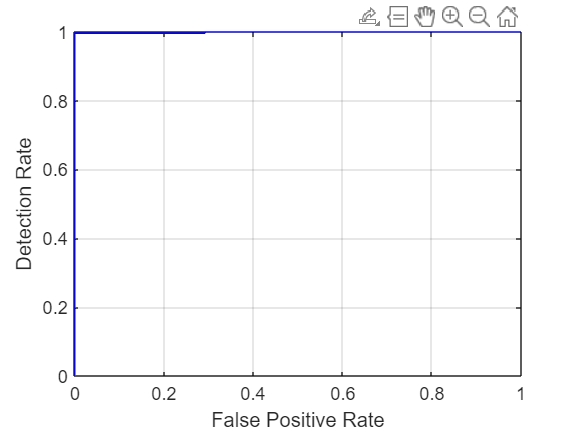



test_labels=double(nominal(imdsTest.Labels));

% ROC Curve - Our target class is the first class in this scenario.
[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');hold on;
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');


% Area under the ROC value
AUC

AUC = single
0.9989


cm = confusionmat(actual_labels, predicted_labels);
cmt = cm'

cmt =    254     0
     2   654



diagonal = diag(cmt)

diagonal =    254
   654


sum_of_rows = sum(cmt, 2)

sum_of_rows =    254
   656



precision = diagonal ./ sum_of_rows

precision =     1.0000
    0.9970


overall_precision = mean(precision)

overall_precision = 0.9985


sum_of_columns = sum(cmt, 1)

sum_of_columns =    256   654



recall = diagonal ./ sum_of_columns'

recall =     0.9922
    1.0000


overall_recall = mean(recall)

overall_recall = 0.9961


f1_score = 2*((overall_precision*overall_recall)/(overall_precision+overall_recall))

f1_score = 0.9973

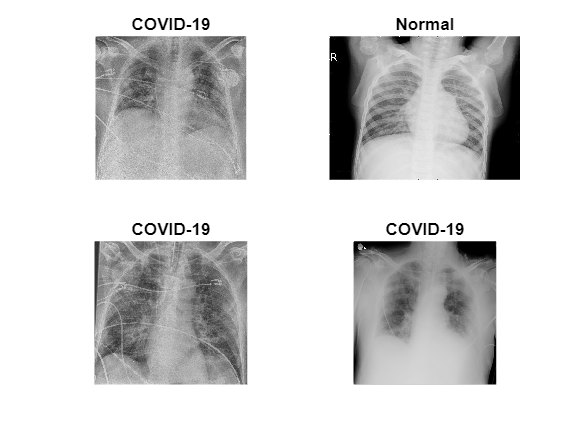




numTrainImages = numel(imds.Labels);
idx = randperm(numTrainImages,4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imds,idx(i));
    imshow(I), title(imds.Labels(idx(i)))
end

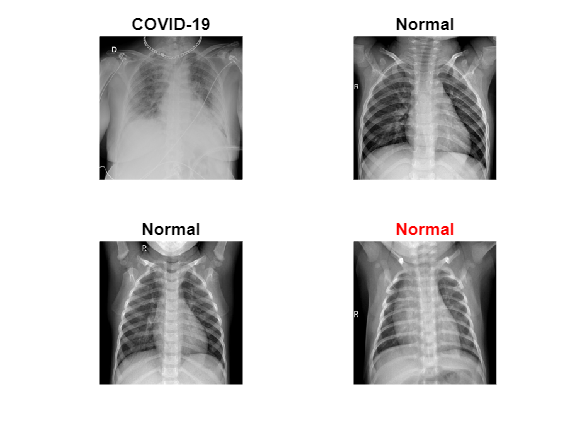



[YPred,scores] = classify(netTransfer,imdsValid);
YValidation = imdsValidation.Labels;


idx = randperm(numel(imdsValid.Files),4);
figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValid,idx(i));
    imshow(I)
    label = YPred(idx(i));
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
end

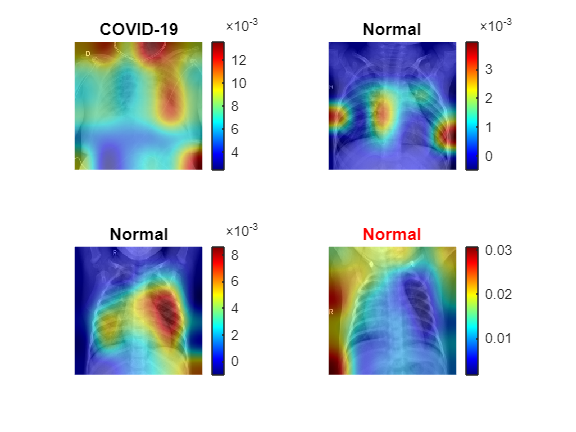



%Grad-CAM

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValid,idx(i));
    I_resized = imresize(I,netTransfer.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    % scoreMap = gradCAM(netTransfer,I_resized,label);
    scoreMap = gradCAM(netTransfer,I_resized,label);
    alpha = 0.5;
    % plotGradCAM(I_resized,scoreMap,alpha);
    % imshow(I_resized)
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    colorbar
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end

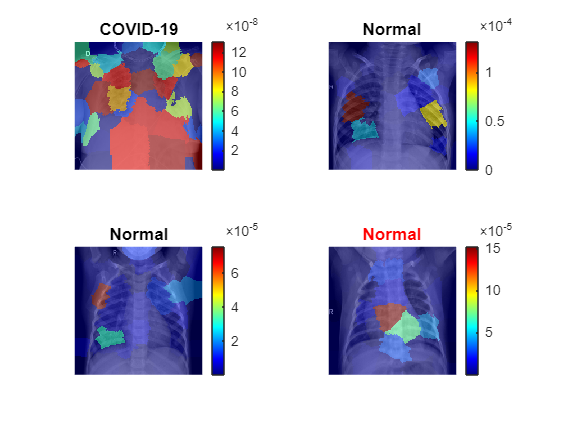



%LIME

figure
for i = 1:4
    subplot(2,2,i)
    I = readimage(imdsValid,idx(i));
    I_resized = imresize(I,netTransfer.Layers(1).InputSize(1:2));
    label = YPred(idx(i));
    scoreMap = imageLIME(netTransfer,I_resized,label);
    imshow(I_resized)
    hold on
    imagesc(scoreMap,'AlphaData',0.5)
    colormap jet
    colorbar
    if(YPred(idx(i)) == YValidation(idx(i)))
        title(string(label), 'Color','black');
    else
        title(string(label), 'Color','red');
    end
    hold off
end

function Iout=preprocess_images(filename,desired_size)



% Read the Image
I=imread(filename);

% Some images might be grayscale, replicate the image 3 times to
% create an RGB image.

if ismatrix(I)
  I=cat(3,I,I,I);
end

% Conversion to Double for calculation purposes
I=double(I);

% Mean Calculation
Ir=I(:,:,1);mu_red=mean(Ir(:));
Ig=I(:,:,2);mu_green=mean(Ig(:));
Ib=I(:,:,3);mu_blue=mean(Ib(:));
mean_value=(mu_red+mu_green+mu_blue)/3;

% Scaling the Image for Color constancy
Iout(:,:,1)=I(:,:,1)*mean_value/mu_red;
Iout(:,:,2)=I(:,:,2)*mean_value/mu_green;
Iout(:,:,3)=I(:,:,3)*mean_value/mu_blue;

% Converting it back to uint8
Iout=uint8(Iout);

% Resize the image
Iout=imresize(Iout,[desired_size(1) desired_size(2)]);
end


function Iout = preprocess_Xray(filename)
% Read the Filename
I = imread(filename);
% Some images might be RGB, convert them to Grayscale
if ~ismatrix(I)
    I=rgb2gray(I); 
end
% Replicate the image 3 times to create an RGB image
Iout = cat(3,I,I,I);
end


